# Example script illustrating how to fit the CSS model

% specify the index of the voxel to fit
ix = 774; % same voxel used for pRF_model_example_1_linear
%ix = 1945; % TO1
%ix = 1996; % V3AB
%ix = 2036; % V3AB

## Add code to the MATLAB path

addpath(genpath(fullfile(pwd,'code')));

## Load data

% load data from the first dataset
load('dataset01.mat','betamn','betase');

## Load stimuli

load('stimuli.mat','conimages');

## Perform stimulus pre-processing

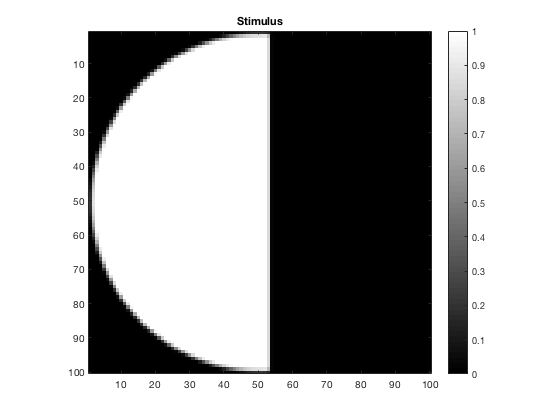

% extract the stimuli we need and then concatenate along the third dimension
stimulus = conimages(1:69);
stimulus = cat(3,stimulus{:});

% resize the stimuli to 100 x 100 (to reduce computational time)
temp = zeros(100,100,size(stimulus,3));
for p=1:size(stimulus,3)
  temp(:,:,p) = imresize(stimulus(:,:,p),[100 100],'cubic');
end
stimulus = temp;

% ensure that all values are between 0 and 1
stimulus(stimulus < 0) = 0;
stimulus(stimulus > 1) = 1;

% inspect one of the stimuli
figure;
imagesc(stimulus(:,:,10));
axis image tight;
colormap(gray);
colorbar;
title('Stimulus');

% reshape stimuli into a "flattened" format: 69 stimuli x 100*100 positions
stimulus = reshape(stimulus,100*100,69)';

## Prepare for model fitting

% to perform model fitting, we will be using fitnonlinearmodel.m.  this function
% is essentially a wrapper around MATLAB's lsqcurvefit.m function.  the benefit
% of fitnonlinearmodel.m is that it simplifies input and output issues, deals with
% resampling (cross-validation and bootstrapping), makes it easy to evaluate multiple
% initial seeds, and makes it easy to perform stepwise fitting of models.
%
% to prepare for the call to fitnonlinearmodel.m, we have to define various 
% input parameters.  this is what we will now do.

% define constants
res = 100;  % resolution of the pre-processed stimuli

% the parameters of the CSS model are [R C S G N] where
%   R is the row index of the center of the 2D Gaussian
%   C is the column index of the center of the 2D Gaussian
%   S is the standard deviation of the 2D Gaussian
%   G is a gain parameter
%   N is the exponent of the power-law nonlinearity

% define the initial seed for the model parameters
seed = [(1+res)/2 (1+res)/2 res 1 0.5];

% define bounds for the model parameters
bounds = [1-res+1 1-res+1 0   -Inf 0;
          2*res-1 2*res-1 Inf  Inf Inf];

% fitnonlinearmodel.m provides the capacity to perform stepwise fitting.
% here, we define a version of bounds where we insert a NaN in the first
% row in the spot that corresponds to the exponent parameter.  this 
% indicates to fix the exponent parameter and not optimize it.
boundsFIX = bounds;
boundsFIX(1,5) = NaN;

% issue a dummy call to makegaussian2d.m to pre-compute xx and yy.
% these variables are re-used to achieve faster computation.
[d,xx,yy] = makegaussian2d(res,2,2,2,2);

% we will now define a function that implements the CSS model.  this function
% accepts a set of parameters (pp, a vector of size 1 x 5) and a set of stimuli 
% (dd, a matrix of size A x 100*100) and outputs the predicted response to those 
% stimuli (as a vector of size A x 1).  for compactness, we implement this 
% function as an anonymous function where the parameters are given by pp
% and the stimuli are given by dd.
modelfunCSS       = @(pp,dd) pp(4)*((dd*vflatten(makegaussian2d(res,pp(1),pp(2),pp(3),pp(3),xx,yy,0,0)/(2*pi*pp(3)^2))).^pp(5));

modelfunLinear    = @(pp,dd) pp(4)*(dd*vflatten(makegaussian2d(res,pp(1),pp(2),pp(3),pp(3),xx,yy,0,0)/(2*pi*pp(3)^2)));


% notice that the overall structure of the model is 
%   RESP = GAIN*(STIM*GAU).^N
% where STIM*GAU represents the dot product between the stimulus and the 2D Gaussian.
% also, note that the division by (2*pi*pp(3)^2) makes it such that the integral
% of the Gaussian is equal to 1 (this aids the interpretation of model parameters).

% now that we have defined modelfun, we are ready to define the final model
% specification.  in the following, we specify a stepwise fitting scheme.
% in the first fit (the first row), we start at the seed and optimize all 
% parameters except the exponent parameter.  in the second fit (the second row),
% we start at the parameters estimated in the first fit and optimize all parameters.
% the purpose of the stepwise fitting is to help converge to a good solution 
% (i.e. avoid local minima).  (the anonymous functions in the second row accept
% a single input, ss, which refers to the parameters estimated in the first fit.)
modelCSS = {{seed       boundsFIX   modelfunCSS} ...
         {@(ss) ss   bounds      @(ss) modelfunCSS}};

modelLinear = {seed(1:4) bounds(:,1:4)  modelfunLinear};

% define the resampling scheme to use.  here, we use 0, which
% means to just fit the data (no cross-validation nor bootstrapping).
resampling = 0;

% define the metric that we will use to quantify goodness-of-fit.
% here, we use a version of the coefficient of determination (R^2)
% in which variance in the data is computed relative to 0.
% this is sensible since the data being fitted are beta weights that
% represent evoked BOLD responses relative to the baseline signal level
% (which corresponds to 0).
metric = @(a,b) calccod(a,b,[],[],0);


% finally, construct the options struct that will be passed to fitnonlinearmodel.m
optCSS = struct( ...
  'stimulus',    stimulus, ...
  'data',        betamn(ix,:)', ...
  'model',       {modelCSS}, ...
  'resampling',  resampling, ...
  'metric',      metric);

optLinear = struct( ...
  'stimulus',    stimulus, ...
  'data',        betamn(ix,:)', ...
  'model',       {modelLinear}, ...
  'resampling',  resampling, ...
  'metric',      metric);

% do a quick inspection of opt
optCSS

optCSS = struct with fields:
      stimulus: [69×10000 double]
          data: [69×1 double]
         model: {{1×3 cell}  {1×3 cell}}
    resampling: 0
        metric: @(a,b)calccod(a,b,[],[],0)


## Fit the model

resultsCSS    = fitnonlinearmodel(optCSS);

*** fitnonlinearmodel: started at 26-Apr-2018 18:35:56. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 1.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 0.500 ].

                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         119.695                          9.44
     1         10         44.9142             10             13      
     2         15         39.2948         9.1906             48      
     3         20         30.1113             20           51.9      
     4         25         30.1113             40           51.9      
     5         30         24.4586             10           50.2      
     6         35         24.4586             20           50.2      
     7         40         21.3712              5           19.1      
     8         45     

resultsLinear = fitnonlinearmodel(optLinear);

*** fitnonlinearmodel: started at 26-Apr-2018 18:35:57. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 1.
      the seed is [50.500 50.500 100.000 1.000 ].

                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         134.289                          5.15
     1         10         72.5733             10           42.6      
     2         15         72.5733        20.2376           42.6      
     3         20         39.2583              5           29.1      
     4         25         39.2583             10           29.1      
     5         30         30.1537            2.5           19.5      
     6         35         23.0681              5             47      
     7         40         22.4753             10            157      
     8         45         15.0977            2

## Inspect the results

% these are the final parameter estimates
resultsCSS.params

ans =    73.5888   16.9884    5.4996    3.3344    0.1535


resultsLinear.params

ans =   119.7321  -50.7910   38.4031  254.1581


% this is the R^2 between the model fit and the data
resultsCSS.trainperformance

ans = 92.9771


% compare to the linear model fit
resultsLinear.trainperformance

ans = 90.2854

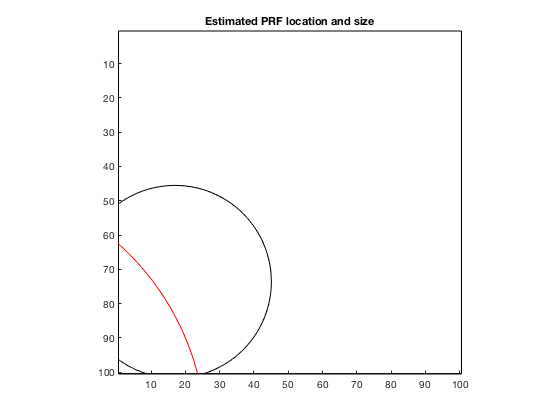

% visualize the parameter estimates
figure; hold on;
pp = resultsCSS.params;
  % draw a circle indicating the PRF location +/- 2 PRF sizes.
  % PRF size is defined as S/sqrt(N).
drawellipse(pp(2),pp(1),0,2*pp(3)/sqrt(pp(5)),2*pp(3)/sqrt(pp(5)),[],[],'k');
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Estimated PRF location and size');

pp = resultsLinear.params;
  % draw a circle indicating the PRF location +/- 2 PRF sizes.
  % PRF size is defined as S/sqrt(N).
drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3),[],[],'r');

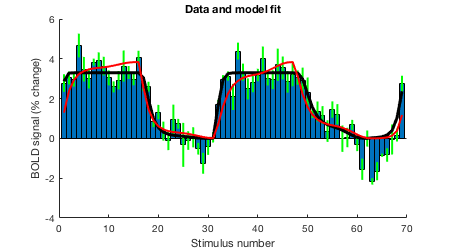

% visualize the data and the model fit
figure; setfigurepos([100 100 450 250]); hold on;
bar(betamn(ix,:),1);
errorbar2(1:69,betamn(ix,:),betase(ix,:),'v','g-','LineWidth',2);
modelfit = modelfunCSS(resultsCSS.params,stimulus);
plot(1:69,modelfit,'k-','LineWidth',3);
ax = axis;
axis([0 70 ax(3:4)]);
xlabel('Stimulus number');
ylabel('BOLD signal (% change)');
title('Data and model fit');

modelfitLinear = modelfunLinear(resultsLinear.params,stimulus);
plot(1:69,modelfitLinear,'r-','LineWidth',2);

## Try a different resampling scheme: cross-validation

% define an options struct that specifies leave-one-out cross-validation
optXVAL = optCSS;
optXVAL.resampling = -2*(eye(69) - 0.5);
optXVAL.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsXVALCSS = fitnonlinearmodel(optXVAL);

*** fitnonlinearmodel: started at 26-Apr-2018 18:36:00. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 69.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 0.500 ].
      the estimated parameters are [75.673 15.873 13.019 4.309 0.500 ].
      for model 2 of 2, the seed is [75.673 15.873 13.019 4.309 0.500 ].
      the estimated parameters are [73.623 16.612 5.078 3.322 0.133 ].
    trainperformance is 92.85. testperformance is 99.64.
  starting resampling case 2 of 69.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 0.500 ].
      the estimated parameters are [77.674 11.500 14.143 4.948 0.500 ].
      for model 2 of 2, the seed is [77.674 11.500 14.143 4.948 0.500 ].
      the estimated parameters are [73.600 16.939 5.496 3.342 0.153 ].
    trainperformance is 92.83. testperformance is 99.33.
  starting resampling case 3 of 69.
      for model 1

% this is the R^2 between the model predictions and the data.
% notice that this cross-validated R^2 is lower than the
% R^2 of the full fit obtained previously.
resultsXVALCSS.aggregatedtestperformance

ans = 92.2484

## Try a different resampling scheme: bootstrapping

% define an options struct that specifies 25 bootstraps (i.e. draw 
% with replacement from the 69 data points5
optBOOT = optCSS;
optBOOT.resampling = {50 0};  % the 0 sets the random-number seed to 0
optBOOT.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsBOOTCSS = fitnonlinearmodel(optBOOT);

*** fitnonlinearmodel: started at 26-Apr-2018 18:36:56. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 50.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 0.500 ].
      the estimated parameters are [125.225 -66.929 24.746 378.218 0.500 ].
      for model 2 of 2, the seed is [125.225 -66.929 24.746 378.218 0.500 ].
      the estimated parameters are [73.418 17.523 4.169 3.175 0.104 ].
    trainperformance is 91.88. testperformance is NaN.
  starting resampling case 2 of 50.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 0.500 ].
      the estimated parameters are [74.149 14.065 13.592 4.474 0.500 ].
      for model 2 of 2, the seed is [74.149 14.065 13.592 4.474 0.500 ].
      the estimated parameters are [73.468 15.940 6.520 3.412 0.176 ].
    trainperformance is 93.34. testperformance is NaN.
  starting resampling case 3 of 50.
      for mod


optBOOT = optLinear;
optBOOT.resampling = {50 0};  % the 0 sets the random-number seed to 0
optBOOT.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsBOOTLinear = fitnonlinearmodel(optBOOT);

*** fitnonlinearmodel: started at 26-Apr-2018 18:37:40. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [127.319 -97.999 35.358 17098.482 ].
    trainperformance is 90.24. testperformance is NaN.
  starting resampling case 2 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [76.906 8.156 22.631 9.867 ].
    trainperformance is 89.91. testperformance is NaN.
  starting resampling case 3 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [117.628 -62.596 37.744 492.201 ].
    trainperformance is 93.17. testperformance is NaN.
  starting resampling case 4 of 50.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [138.342 -97.995 36.879 17773.834 ].
    trainperformance is 85.98. 

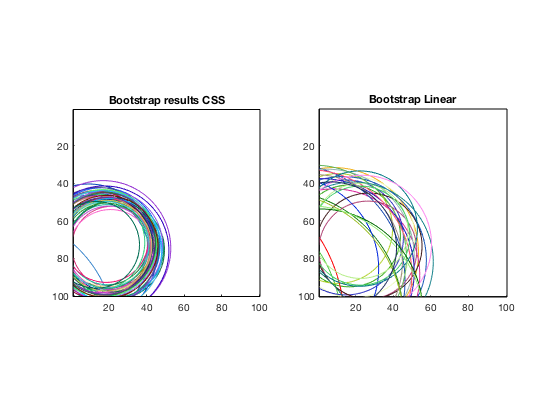

% visualize the parameter estimates
figure; hold on;
subplot(1,2,1)
for p=1:size(resultsBOOTCSS.params,1)
  pp = resultsBOOTCSS.params(p,:);
  h = drawellipse(pp(2),pp(1),0,2*pp(3)/sqrt(pp(5)),2*pp(3)/sqrt(pp(5)));
  set(h,'Color',rand(1,3));
end
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Bootstrap results CSS');

% visualize the parameter estimates
subplot(1,2,2); hold on;
for p=1:size(resultsBOOTLinear.params,1)
  pp = resultsBOOTLinear.params(p,:);
  h = drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3));
  set(h,'Color',rand(1,3));
end
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Bootstrap Linear');

## Example of how to simulate model responses

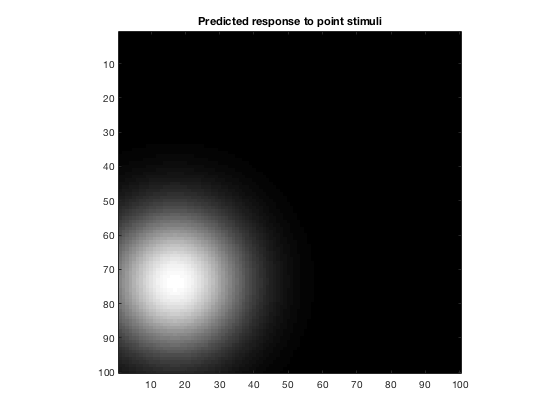

% let's take the model fitted to the full dataset and compute
% the predicted response of the model to some new stimuli.

% let's compute the response of the model to a point stimulus
% that is positioned at different locations in the visual field.
resp = zeros(res,res);
for r=1:res
  for c=1:res
    stim0 = zeros(res,res);
    stim0(r,c) = 1;
    resp(r,c) = modelfunCSS(resultsCSS.params,flatten(stim0));
  end
end

% visualize the results
figure;
mx = max(resp(:));
imagesc(resp,[0 mx]);
axis image tight;
colormap(gray);
title('Predicted response to point stimuli');

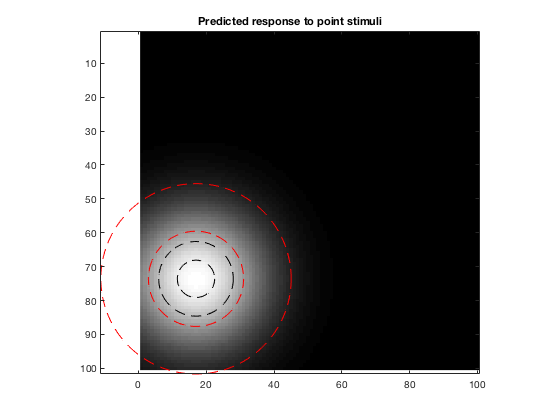

% notice that the results are consistent with the definition
% of PRF size as S/sqrt(N).
pp = resultsCSS.params;
h = drawellipse(pp(2),pp(1),0,pp(3),pp(3), [], [], 'k--');
h = drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3), [], [], 'k--');

h = drawellipse(pp(2),pp(1),0,pp(3)/sqrt(pp(5)),pp(3)/sqrt(pp(5)), [], [], 'r--');
h = drawellipse(pp(2),pp(1),0,2*pp(3)/sqrt(pp(5)),2*pp(3)/sqrt(pp(5)), [], [], 'r--');